%% Parameters
numCells = 10000;          % Total number of cells
fluorMean1 = [200, 500];   % Mean fluorescence for two populations in Channel 1
fluorStd1 = [50, 100];     % Std deviation for Channel 1

fluorMean2 = [400, 100];   % Mean fluorescence for two populations in Channel 2
fluorStd2 = [70, 60];      % Std deviation for Channel 2

gateX = [250 550 550 250]; % Polygon gate vertices on X-axis (Channel 1)
gateY = [150 150 350 350]; % Polygon gate vertices on Y-axis (Channel 2)

%% Generate synthetic data
% Population 1
pop1_x = fluorMean1(1) + fluorStd1(1)*randn(numCells/2, 1);
pop1_y = fluorMean2(1) + fluorStd2(1)*randn(numCells/2, 1);

% Population 2
pop2_x = fluorMean1(2) + fluorStd1(2)*randn(numCells/2, 1);
pop2_y = fluorMean2(2) + fluorStd2(2)*randn(numCells/2, 1);

allCells_x = [pop1_x; pop2_x];
allCells_y = [pop1_y; pop2_y];

%% Gating
inGate = inpolygon(allCells_x, allCells_y, gateX, gateY);

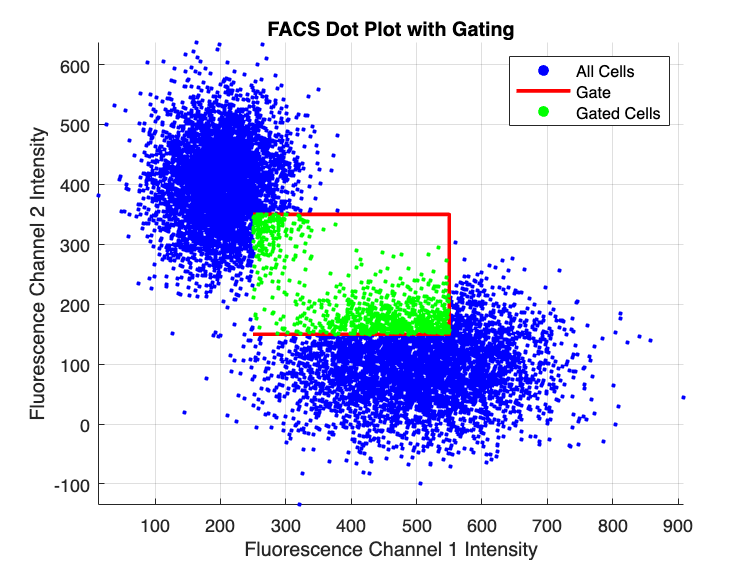

%% Plotting
figure;

% Dot plot of all cells
scatter(allCells_x, allCells_y, 5, 'b', 'filled');
hold on;
plot(gateX, gateY, 'r-', 'LineWidth', 2); % Plot the gate
scatter(allCells_x(inGate), allCells_y(inGate), 5, 'g', 'filled'); % Highlight gated cells in green

xlabel('Fluorescence Channel 1 Intensity');
ylabel('Fluorescence Channel 2 Intensity');
title('FACS Dot Plot with Gating');
legend('All Cells', 'Gate', 'Gated Cells');
grid on;
axis tight;